# Furuta Pendulum Model

By Justin Lesko

## Overview

This document serves as a mathematical model for Justin's Furuta Pendulum Thesis.

clear all;
clc;
close all;
%Set up all symbols used in the symbolic derivation
syms theta1 theta2 l1 l2 l3 l4 m1 m2 b1 b2 omega1 omega2 J1xx J1yy J1zz J2xx J2yy J2zz g tau1 tau2 alpha1 alpha2 Km Lm Rm
%Calculate the equivalent mass matrix found from the EOM derivation
M11 = m1*l1^2+J1zz+m2*l2^2+(sin(theta2)^2)*(m2*l3^2+J2yy)+cos(theta2)^2*(J2xx);
M12 = m2*l3*l2*cos(theta2);
M21 = (l3*l2*m2*cos(theta2));
M22 = l3^2*m2+J2zz;
M = [M11 M12;
    M21 M22];
%Get EOMs into form of ddx = f() for linearization
A1 = tau1-(omega1*b1+omega1*omega2*sin(2*theta2)*(m2*l3^2+J2yy-J2xx)-omega2^2*(m2*l3*l2*sin(theta2)));
A2 = tau2-(b2*omega2-((omega1^2)/2)*sin(2*theta2)*(m2*l3^2-J2xx+J2yy)+sin(theta2)*m2*g*l3);
A = [A1;
    A2];
alphas = (M^-1)*(A);
%In order to properly control the pendulum, use jacobian linearization to
%get the equations into state space
A = jacobian([alphas(1), alphas(2)], [theta1; theta2; omega1; omega2;]);
B = jacobian([alphas(1), alphas(2)], [tau1; tau2;]);
%State linearized about:
theta1 = 0;
theta2 = pi;
omega1 = 0;
omega2 = 0;
tau1 = 0;
tau2 = 0;
% vpa(eval(A),2);
% vpa(eval(B),2);
% Set up state space from jacobians with desired state 
% vector x = [theta1; theta2; omega1; omega2]
A = [0 0 1 0 0;
    0 0 0 1 0;
    A [B(1,1)*Km; B(2,1)*Km];
    0 0 -Km/Lm 0 -Rm/Lm];
% B = [0 0;
%     0 0;
%     0 B(1,2);
%     0 B(2,2);
%     1/Lm 0];
%EOM's were calculated with disturbance torque and arm torque as inputs 1
%and 2
B1 = [0;
    0;
    0;
    0;
    1/Lm];
B2 = [0;
    0;
    B(1,2);
    B(2,2);
    0];
m1 = 0.3;
m2 = 0.075;
l1 = 0.15;
l2 = 0.278;
l3 = 0.148;
l4 = 0.3;
b1 =1e-4;
b2 = 2.8e-4;
J1xx = 0;
J1yy = 0;
J1zz = 2.48e-2;
J2xx = 0;
J2yy = 3.86e-3;
J2zz = 3.86e-3;
Km = 0.090;
Lm = 0.005;
Rm = 7.8;
g = 9.81;
A = double((eval(A)))

A = 1.0e+03 *

         0         0    0.0010         0         0
         0         0         0    0.0010         0
         0    0.0017   -0.0000   -0.0000    0.0025
         0    0.0207   -0.0000   -0.0001    0.0014
         0         0   -0.0180         0   -1.5600


B1 = double((eval(B1)))

B1 =      0
     0
     0
     0
   200


B2 = double((eval(B2)))

B2 =          0
         0
   15.7449
  190.5549
         0


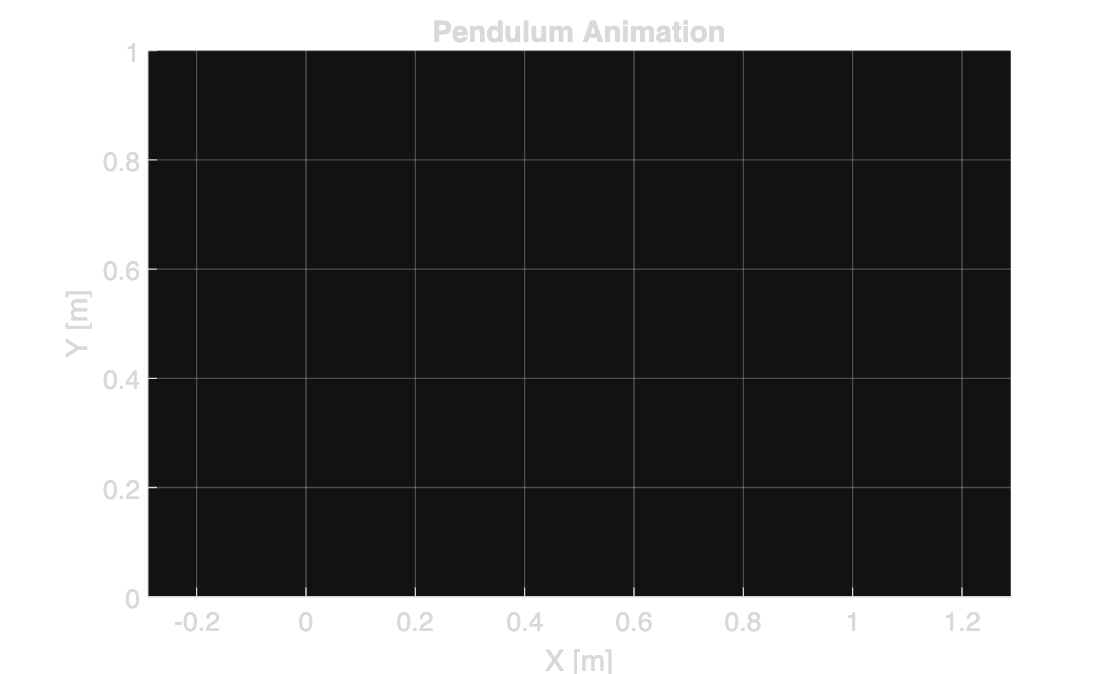

C = [1 0 0 0 0;
    0 1 0 0 0;
    0 0 1 0 0;
    0 0 0 1 0;
    0 0 0 0 1];
D = [0;
    0;
    0;
    0;
    1];
sys = ss(A, B1, C, D);
Q = [2 0 0 0 0;
    0 10 0 0 0;
    0 0 1 0 0;
    0 0 0 1 0;
    0 0 0 0 1];
R = 1;
[K,S,P] = lqr(sys, Q, R);
newsys = ss(A-B1*K, B1, C, D);
[yout1, tout1] = (step(sys));
[yout2, tout2] = (step(newsys));
% fig0 = figure();
% hold on;
% subplot(2,1,1);
% plot(tout1, yout1(:, 2));
% subplot(2,1,2);
% plot(tout2, yout2(:, 2));
% xlim([0 2]);
% hold off;

x0 = [0;
    0;
    0;
    0;
    0];
x(:, 1)=x0;
x_controlled(:,1) = x0;
i=1;
dt = 0.001;
c2dsys = c2d(sys, dt);
tf = 6;
time(1) = 0;
P0 = [0 0 0];
N=tf/dt+1;
tau2_d=zeros(N,1);
positions=[100:400];
tau2_d(positions)=0.1;
figure('Color','w');
axis equal; 
grid on;
xlabel('X [m]'); 
ylabel('Y [m]'); 
zlabel('Z [m]');
title('Pendulum Animation');
hold on;
for t = 0:dt:tf
    %dx(:, i) = A*x(:, i);
    %x(:, i+1) = x(:, i)+dx(:, i)*dt;
    cla;
    hold on;
    u(i) = -K*x_controlled(:, i);
    dx_controlled(:,i) = A*x_controlled(:, i)+B1*u(i)+B2*tau2_d(i);
    x_controlled(:, i+1) = x_controlled(:, i)+dx_controlled(:, i)*dt;
    time(i+1) = dt*(i);
    theta1 = x_controlled(1, i);
    theta2 = x_controlled(2, i);
    i = i+1;
    % [P1, P2] = calculatePlotPosition(theta1, theta2, l2, l4);
    % plot3([P0(1), P1(1)], [P0(2), P1(2)], [P0(3), P1(3)], 'k-', 'LineWidth', 2);
    % plot3([P1(1), P2(1)], [P1(2), P2(2)], [P1(3), P2(3)], 'b-', 'LineWidth', 2);
    % hold off;
    % grid on;
    % xlim([-0.50 0.5]);
    % ylim([-0.50 0.5]);
    % zlim([-0.5 0.5]);
    % view([312.222 24.876]);
    % drawnow;
end
hold off;

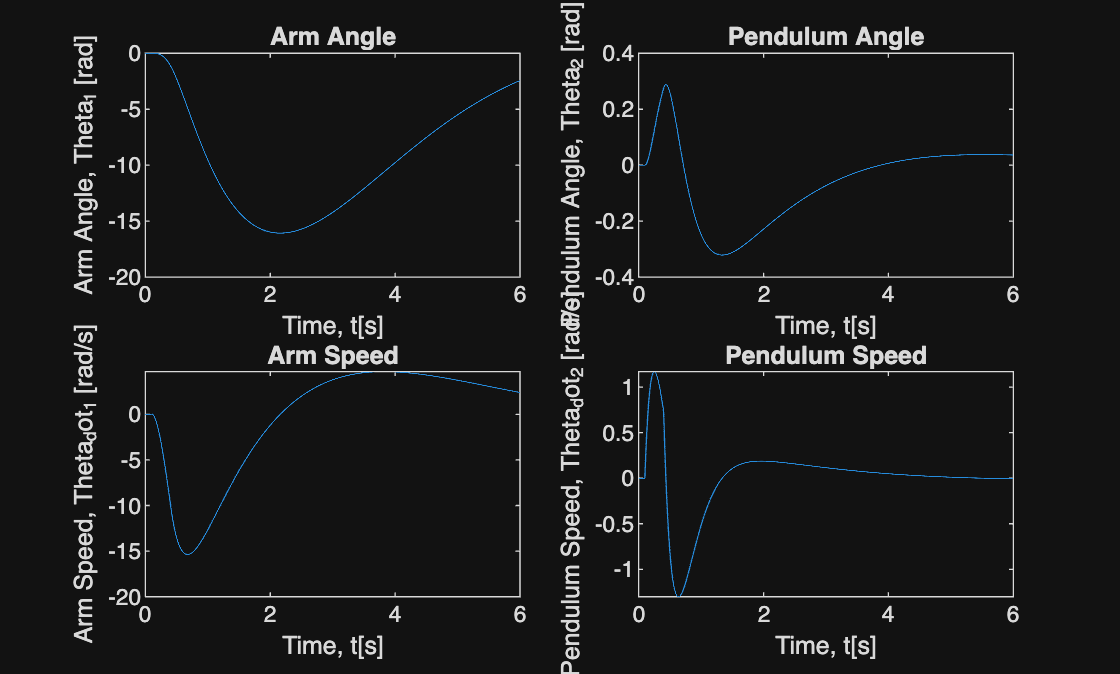

% fig1 = figure();
% plot(time, x_controlled(1, :));
% fig2 = figure();
% plot(time, x_controlled(2, :));
% fig3 = figure();
% plot(time, x_controlled(3, :));
% fig4 = figure();
% plot(time, x_controlled(4, :));
fig5 = figure();
hold on;

subplot(2,2,1);
plot(time, x_controlled(1,:));
title('Arm Angle');
xlabel('Time, t[s]');
ylabel('Arm Angle, Theta_1 [rad]');
xlim([0 tf]);

subplot(2,2,2);
plot(time, x_controlled(2,:));
title('Pendulum Angle');
xlabel('Time, t[s]');
ylabel('Pendulum Angle, Theta_2 [rad]');
xlim([0 tf]);

subplot(2,2,3);
plot(time, x_controlled(3,:));
title('Arm Speed');
xlabel('Time, t[s]');
ylabel('Arm Speed, Theta_dot_1 [rad/s]');
xlim([0 tf]);

subplot(2,2,4);
plot(time, x_controlled(4,:));
title('Pendulum Speed');
xlabel('Time, t[s]');
ylabel('Pendulum Speed, Theta_dot_2 [rad/s]');
xlim([0 tf]);


hold off;


%sys =ss(A,B,C,D)
function [P1 P2] = calculatePlotPosition(theta1, theta2, l1, l2)
R1 = [cos(theta1) -sin(theta1) 0;
      -sin(theta1) cos(theta1) 0;
      0 0 1];
R2 = [0 sin(pi+theta2) -cos(pi+theta2);
      0 cos(pi+theta2) sin(pi+theta2);
      1 0 0];
r1 = [l1;
    0;
    0];
r2 = [l2;
    0;
    0];
P1 = R1*r1;
P2 = P1+R2*r2;
end